clear
asset_path = "../docs/assets/";
% Discrete Cosine Transform compression
% See https://www.mathworks.com/help/images/discrete-cosine-transform.html
img = imread('theory/deer.pgm');
if size(img, 3) == 3
    img = rgb2gray(img);
end
img = im2double(img);
original_dims = size(img);


% IMPORTANT! Later we perform 8x8 transformations to the image with DCT
% matricies. This means that our image's dimensions need to be divisible by
% 8. This is why I cut the image by 1 row pixel and 3 column pixels.
BlockSize = 8;
trim_h = mod(original_dims(1), 8);
trim_w = mod(original_dims(2), 8);
img = img(1:original_dims(1)-trim_h, 1:original_dims(2)-trim_w);
trimmed_dims = size(img);

% Perform 8x8 dct transformations
Block = [BlockSize BlockSize];
T = dctmtx(BlockSize);
dctProccess = @(block_struct) T * block_struct.data * T';
B = blockproc(img,Block,dctProccess);

% Define indicies order from highest to lowest
% check this order
zig_order = [
   1  2  6  7 15 16 28 29
   3  5  8 14 17 27 30 43
   4  9 13 18 26 31 42 44
   10 12 19 25 32 41 45 54
   11 20 24 33 40 46 53 55
   21 23 34 39 47 52 56 61
   22 35 38 48 51 57 60 62
   36 37 49 50 58 59 63 64
]

zig_order =      1     2     6     7    15    16    28    29
     3     5     8    14    17    27    30    43
     4     9    13    18    26    31    42    44
    10    12    19    25    32    41    45    54
    11    20    24    33    40    46    53    55
    21    23    34    39    47    52    56    61
    22    35    38    48    51    57    60    62
    36    37    49    50    58    59    63    64



energy_order = zeros([BlockSize*BlockSize, 2]);
for i = 1:BlockSize*BlockSize
    [row, col] = find(zig_order == i);
    energy_order(i, 1) = row;
    energy_order(i, 2) = col;
end

% Itterate t
snrs = zeros([1 BlockSize*BlockSize]);
ssims = zeros(size(snrs));
for i = 1:BlockSize*BlockSize
    mask = zeros(BlockSize);
    for j = 1:i
        mask(energy_order(j, 1), energy_order(j, 2)) = 1;
    end

    masked = blockproc(B,Block,@(block_struct) mask .* block_struct.data);
    invdct = @(block_struct) T' * block_struct.data * T;
    compressed = blockproc(masked,Block,invdct);
    snrs(i) = psnr(compressed, img);
    ssims(i) = ssim(compressed, img);
    disp(i)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64



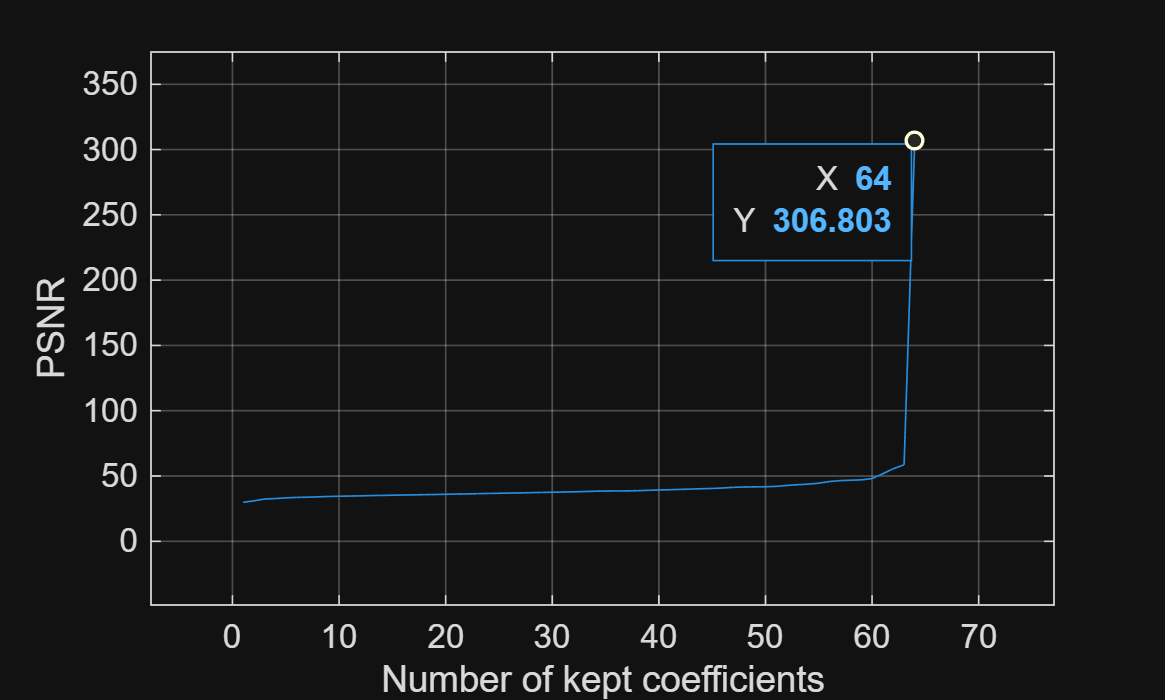

plot(snrs)
xlabel("Number of kept coefficients");
ylabel("PSNR");
grid on;

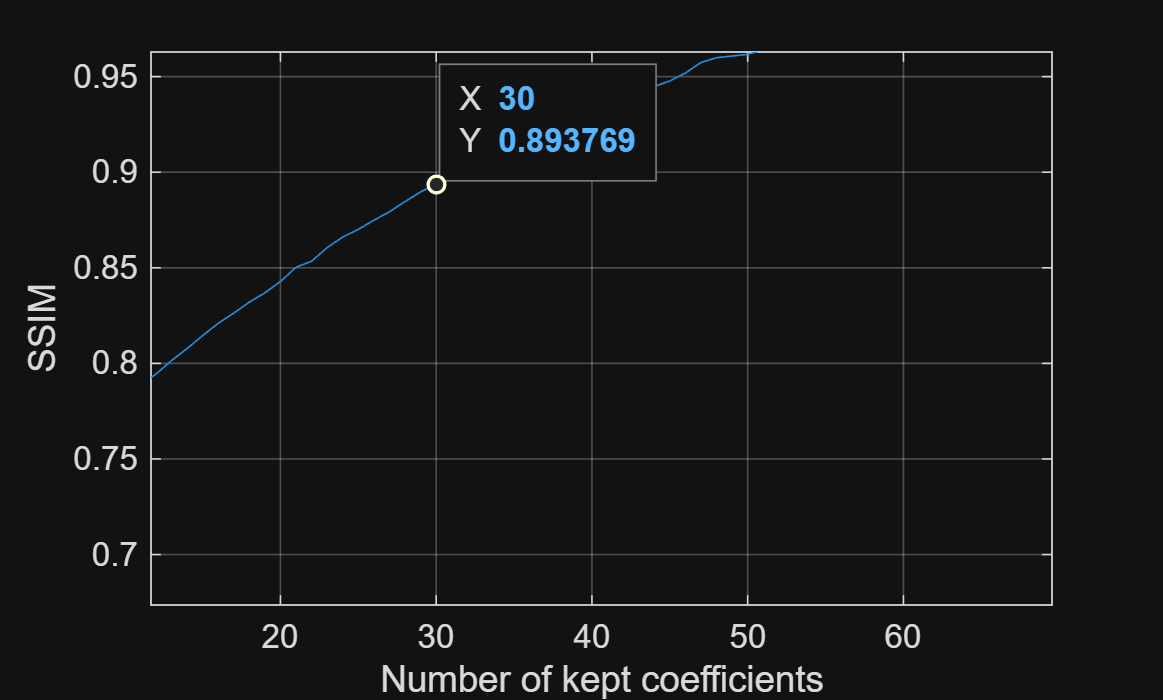

plot(ssims)
xlabel("Number of kept coefficients");
ylabel("SSIM");
grid on;

num_coeffs_per_block = 1:64;
block_dims = trimmed_dims ./ 8

block_dims =    330   505


num_blocks = block_dims(1) * block_dims(2)

num_blocks = 166650

num_saved_values = num_coeffs_per_block * num_blocks

num_saved_values =       166650      333300      499950      666600      833250      999900     1166550     1333200     1499850     1666500     1833150     1999800     2166450     2333100     2499750     2666400     2833050     2999700     3166350     3333000     3499650     3666300     3832950     3999600     4166250     4332900     4499550     4666200     4832850     4999500     5166150     5332800     5499450     5666100     5832750     5999400     6166050     6332700     6499350     6666000     6832650     6999300     7165950     7332600     7499250     7665900     7832550     7999200     8165850     8332500


uncompressed_num_coeffs = size(B, 1) *size(B, 2)

uncompressed_num_coeffs = 10665600

percent_useful_values = num_saved_values ./ uncompressed_num_coeffs

percent_useful_values =     0.0156    0.0312    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1562    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2812    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4062    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5312    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250    0.6406    0.6562    0.6719    0.6875    0.7031    0.7188    0.7344    0.7500    0.7656    0.7812


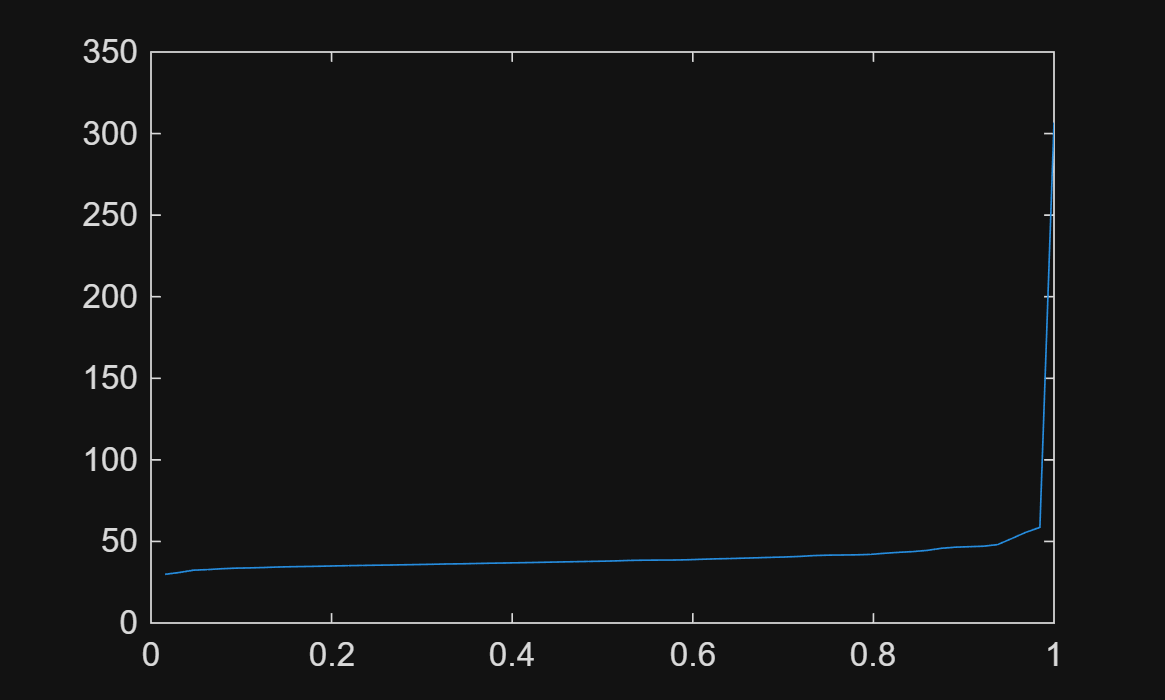

plot(percent_useful_values, snrs)

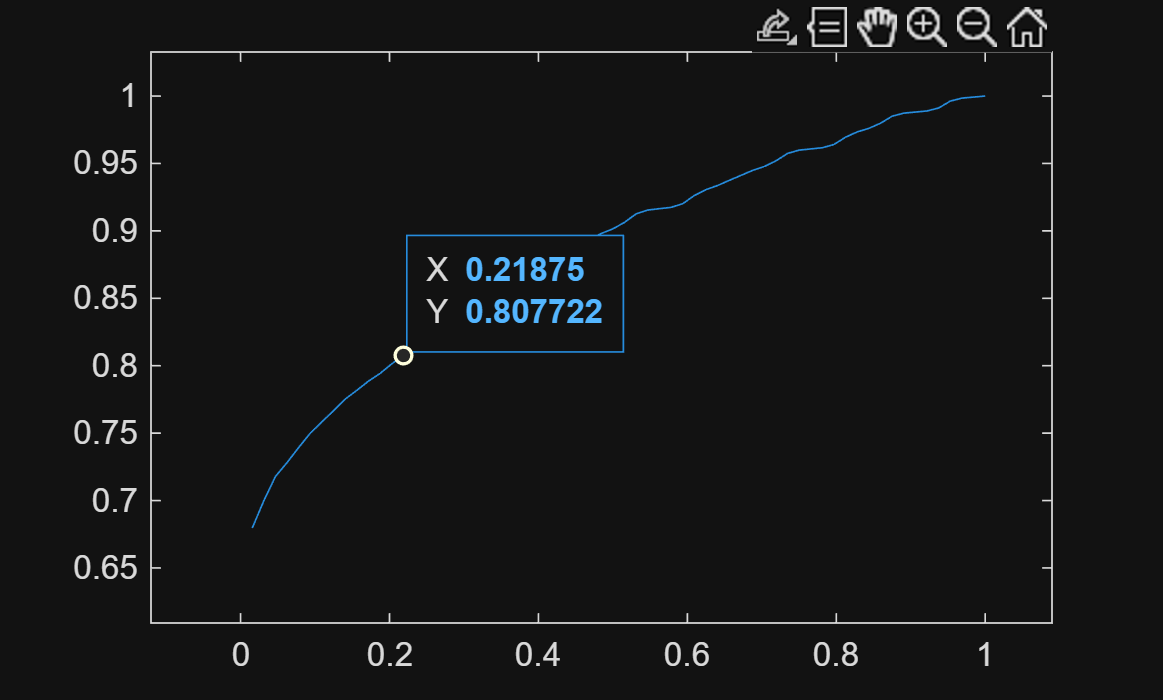

plot(percent_useful_values, ssims)